# **Create the Ramsey-Cass-Koopmans model using MATLAB**

This example shows how to define and solve the Ramsey-Cass-Koopmans model (a system of coupled ODEs) using MATLAB.

*Copyright 2016-2023 The MathWorks, Inc.*

## Define the model parameters.

See [`defineRCKParams`](matlab: edit defineRCKParams) for more details.

defineRCKParams

## Parametrize the coupled system of equations.

See [`RCK_Equations`](matlab: edit RCK_Equations) for more details.

RCK_Fun = @(t, Y) RCK_Equations(t, Y, params);

## Both per-capita wealth and consumption remain nonnegative over time.

We use [`odeset`](matlab: doc odeset) to define options for MATLAB's ODE solvers.

opts = odeset("NonNegative", [1, 2]);

## Define initial values for per-capita wealth and consumption.

We set $Y_0 = \left[\begin{array}{c}k_0\\ c_0\end{array}\right]=\left[\begin{array}{c}25\\ 2\end{array}\right]$.

Y0 = [25; 2];

## Create a time vector for the system.

In this example, time runs from $t_0=0$ to $t_{\text{end}}=1.5$.

t = linspace(0, 1.5, 5000);

## Solve the coupled system.

We use [`ode45`](matlab: doc ode45) to solve the system of ODEs defined by the Ramsey-Cass-Koopmans equations.

[~, Y] = ode45(RCK_Fun, t, Y0, opts);

Extract the per-capita wealth $k = k(t)$ and the per-capita consumption $c=c(t)$ separately.

k_out = Y(:, 1);
c_out = Y(:, 2);

## Visualize the resulting trajectory on the phase plane.

Start by animating the solution trajectory on the $(k, c)$ phase plane.

figure
comet(k_out, c_out, 0.5)
hold on
axLims = axis();

Only keep the comet tail for the legend. Adjust the appearance of the comet head and tail.

cometComponents = gca().Children;
tail = findobj(cometComponents, "Tag", "tail");
set(tail, "LineWidth", 1.5, "Color", "k")
head = findobj(cometComponents, "Tag", "head");
set(head, "Marker", "v", "MarkerSize", 10, "Color", "k", "MarkerFaceColor", "k")
set(setdiff(cometComponents, tail), "HandleVisibility", "off")

Show the steady-state curve $\frac{dk}{dt}=0$.

plot(params.k_fine, params.c_star, "r", "LineWidth", 2)
xlabel("$k$ (capital per capita)", "Interpreter", "latex")
ylabel("$c$ (consumption per capita)", "Interpreter", "latex")
title("Ramsey-Cass-Koopmans Capital-Consumption Phase Plane")
grid on

Add the legend.

legend(["ODE45 solution, $(k_0, c_0)$ = (" + Y0(1) + ", " + Y0(2) + ")", ...
        "$dk/dt = 0$"], "Location", "best", "Interpreter", "LaTeX")

Restore the original axes limits.

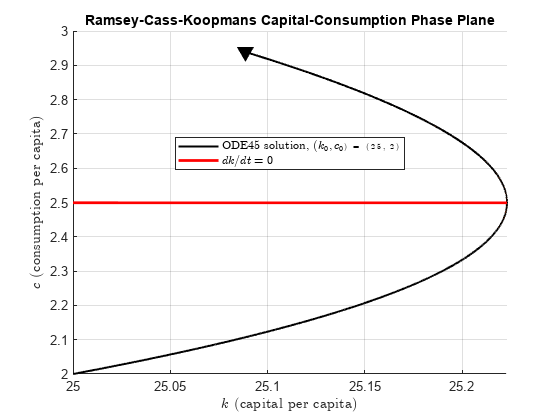

axis([axLims(1:3), Y0(2)+1])